# **Chapter 3     Linear-Quadratic (LQ) Optimal Reinforcement Learning Mechanism in Discrete-Time (Hewer’s Algorithm)**

## **Essence of the Hower’s RL Policy Iteration Algorithm**

The essence of the Hewer algorithm is to use successive approximations (feedback iterations $u_i(x(k)) = -F_ix(k), i=1,2, \cdots$, which is equivalent to the reinforcement learning policy iteration) as follows


$$P_i = \big(A-BF_{i-1} \big)^{\mathrm{T}}P_i \big(A-BF_{i-1} \big) + F_{i-1}^{\mathrm{T}}RF_{i-1} +Q, \qquad i=1,2,3,\cdots \\
F_{i} = -\big( R + B^{\mathrm{T}}P_iB \big)^{-1} B^{\mathrm{T}}P_iA, \qquad \mathrm{with}\ F_0\ \mathrm{stabilizing} \ |\lambda_j\big(A-BF_0 \big)| <1$$


This requires solving in each iteration a discrete-time algebraic Lyapunov equation and updating the approximate feedback gain after initializing the procedure with a stabilizing feedback gain $F_0$, which is much simple and faster than directly solving highly nonlinear algebraic discrete-time Riccati equation (DARE). These iterations converge to the unique stabilizing solution of DARE


$$P=A^{\mathrm{T}}PA +Q - A^{\mathrm{T}}PB\big(R+B^{\mathrm{T}}PB \big)^{-1}B^{\mathrm{T}}PA \\
P_1 \geq P_2 \geq P_3 \geq \cdots \geq P \\
J^{\mathrm{opt}}(x_0) = \frac{1}{2} x_0^{\mathrm{T}}Px_0$$


When $u(k) = u^{\mathrm{opt}}(x(k))$ then $P_i = P$, where $P$ satisfies DARE. Having obtained $P_1$, we can use


$$u_1(k) = -\big( R+B^{\mathrm{T}}P_1B  \big)^{-1} B^{\mathrm{T}}P_1Ax(k) = -F_1x(k)$$


This approximate control leads to


$$J_1(x(k)) = \frac{1}{2} \sum_{m=k}^{\infty} \Big[ x^{\mathrm{T}}(m) \big( Q+F_1^{\mathrm{T}}RF_1\big)x(m) \Big] = \frac{1}{2} x^{\mathrm{T}}(k)P_2x(k) \\
P_2 - \big( A-BF_1\big)^{\mathrm{T}}P_2\big( A-BF_1\big) = Q+F_1^{\mathrm{T}}RF_1$$


This procedure is iteratively repeated


$$u_i(k) = -\big( R+B^{\mathrm{T}}P_iB  \big)^{-1} B^{\mathrm{T}}P_iAx(k) = -F_ix(k) \\
J_i(x(k)) = \frac{1}{2} x^{\mathrm{T}}(k)P_ix(k), \qquad \forall i=0,1, 2, \cdots \\
P_{i+1} - \big( A-BF_i\big)^{\mathrm{T}}P_{i+1}\big( A-BF_i\big) = Q+F_i^{\mathrm{T}}RF_i$$


The generated sequence of $P_i$ matrices has the property 


$$P_1 \geq P_2 \geq P_3 \geq \cdots \geq P$$


where $P$ is the unique stabilizing solution of DARE, and with the approximate performance criterion values converging to the optimal performance criterion value, that is


$$J_0(x(k)) \geq J_1(x(k)) \geq J_2(x(k)) \geq \cdots \geq J_{\mathrm{opt}}(x(k))$$


It was stated and proved in the papers by Hewer that this algorithm has a quadratic rate of convergence.

***Project Report Format: ***

The project reports are supposed to be typed and contain the standard technical paper main parts: introduction (about the general methodology used), problem formulation (what you plan to do and what you are supposed to achieve), main results obtained (obtained simulation results, tables, and figures), discussion/comments (on obtained results and some observations), conclusions, appendix (with MATLAB code), references.

***Project Data:*** 

The project considers a Boeing 747 flight controls system from a very recent paper (see Section 3.6 for details). Assuming level flight at 40,000 ft at a speed of 774 ft/s, and the discretization interval of 1 s, the linearized aircraft dynamic is represented in the discrete-time domain by


$$x(k+1) = Ax(k) + Bu(k)$$


where


$$A= \left[\matrix{ 0.99 & 0.03 & -0.02 & -0.32 \cr 
                         0.01 & 0.47 & 4.7 & 0.0 \cr
                         0.02 & -0.06 & 0.4 & 0.0 \cr
                         0.01 &-0.04 &  0.72 & 0.99} \right], \quad
B = \left[\matrix{ 0.01 & 0.99 \cr
                           -3.44 & 1.66 \cr
                          -0.83 & 0.44 \cr
                          -0.47 & 0.25} \right]$$


The penalty matrices in the corresponding linear-quadratic optimal control problem were selected as, $Q=I_4, R=I_2$. The Lyapunov and Riccati algebraic equations can be solved using the corresponding MATLAB functions “**dlyap**” and “**idare**” or “**dlqr**”. Use **>> help dlyap** or **>> help idare**, … to learn more about the MATLAB functions of interest.

***Hint***: Since matrix *A* is asymptotically stable, that is $|\lambda_j(A)<1$ for every $j=1,2, \cdots,n$, you can use $F_0$ as a zero matrix. Since we are dealing with vectors and matrices, the dimensions of all matrices are important. Hence, in MATLAB we input **>>F0=zeros(2,4)**.

***Project Task:*** 

Running policy iterations of the Hewer algorithm generate a table that shows how the approximate performance values converge per iteration to the optimal values. In general, you need to run only five to six iterations, in a are case nine or ten iterations due to the quadratic convergence of the algorithm. Plot on one figure all approximates feedback controls obtained for $k=1,2,3,4,5$, and on another figure plot the approximate system state trajectories for a selected (the one that performs the worst) state variable for $k=1,2,3,4,5$.

***System Initialization: ***

clear all; close all; clc

The discrete time state space model is given by: 

A=[0.99 0.03 -0.02 -0.32;
    0.01 0.47 4.7 0;
    0.02 -0.06 0.4 0;
    0.01 -0.04 0.72 0.99];
B=[0.01 0.99;
    -3.44 1.66;
    -0.83 0.44;
    -0.47 0.25];
x0=[1;1;1;1]; % system initial conditions

***LQ Control Problem Formalization, Verification, Solution:***

% LQ optimal control problem initialization
Q=eye(4); R=eye(2);

% Test for Controllability and Observability
CO=ctrb(A,B); % forms the controllability matrix
rankCO=rank(CO) % finds the rank of the controllability matrix

rankCO = 4

% the rank is equal to n (system order) implies controllability
OM=obsv(A,Q); % forms the observability matrix
rankOM=rank(OM) % rank equal to n implies observability

rankOM = 4

% Note that the same rank is obtained by using obsv(A,Chol(Q))

% Direct solution of the optimal LQ problem
[Fopt,P]=dlqr(A,B,Q,R);
Jopt=0.5*x0'*P*x0

Jopt = 14.9453

% [X,K,L] = idare(A,B,Q,R)
% Jopt1=0.5*x0'*X*x0

***Reinforcement Learning Solution:***

ev=eig(A);
% Since A is asymptotically stable (all eigenvalues inside of unit circle
% we can use F0 = 0 (pay attention to the dimension of this zero)
F0=zeros(2,4)

F0 =      0     0     0     0
     0     0     0     0


% In general, to find F0 that stabilize the system, 
% we can use the MATLAB function place that finds the feedback
% matrix that places the closed loo (A-B*F0) ev in the desired locations
% lambda_desired=[-0.5; 0.2; -0.1+j*0.5 -0.1-j*0.5] can use complex conjugate ev
% F0=place(A,B,lambda_desired); check eigenvalues of (A-B*F0); evF0=eig(A-B*F0);

***Hewer's Reinforcer***

    
$$P_i = \big(A-BF_{i-1} \big)^{\mathrm{T}}P_i \big(A-BF_{i-1} \big) + F_{i-1}^{\mathrm{T}}RF_{i-1} +Q, \qquad i=1,2,3,\cdots \\
F_{i} = -\big( R + B^{\mathrm{T}}P_iB \big)^{-1} B^{\mathrm{T}}P_iA, \qquad \mathrm{with}\ F_0\ \mathrm{stabilizing} \ |\lambda_j\big(A-BF_0 \big)| <1$$


% Set-up total iteration
Iter=6

Iter = 6

Ji=0;

% Policy iterations of the Hewer algorithm
Pi{1} = dlyap((A-B*F0)',Q+F0'*R*F0);
F{1} = inv(R+B'*Pi{1}*B)*B'*Pi{1}*A;
Ji(1)=0.5*x0'*Pi{1}*x0;
Error(1) = norm((A-B*F{1})'*Pi{1}*(A-B*F{1})-Pi{1}+Q+F{1}'*R*F{1});
for i=2:Iter
    Pi{i}=dlyap((A-B*F{i-1})',Q+F{i-1}'*R*F{i-1});
    i;
    Ji(i)=0.5*x0'*Pi{i}*x0;
    F{i}=inv(R+B'*Pi{i}*B)*B'*Pi{i}*A;
    Error(i) = norm((A-B*F{i})'*Pi{i}*(A-B*F{i})-Pi{i}+Q+F{i}'*R*F{i});
end

***Plotting the obtained results:***

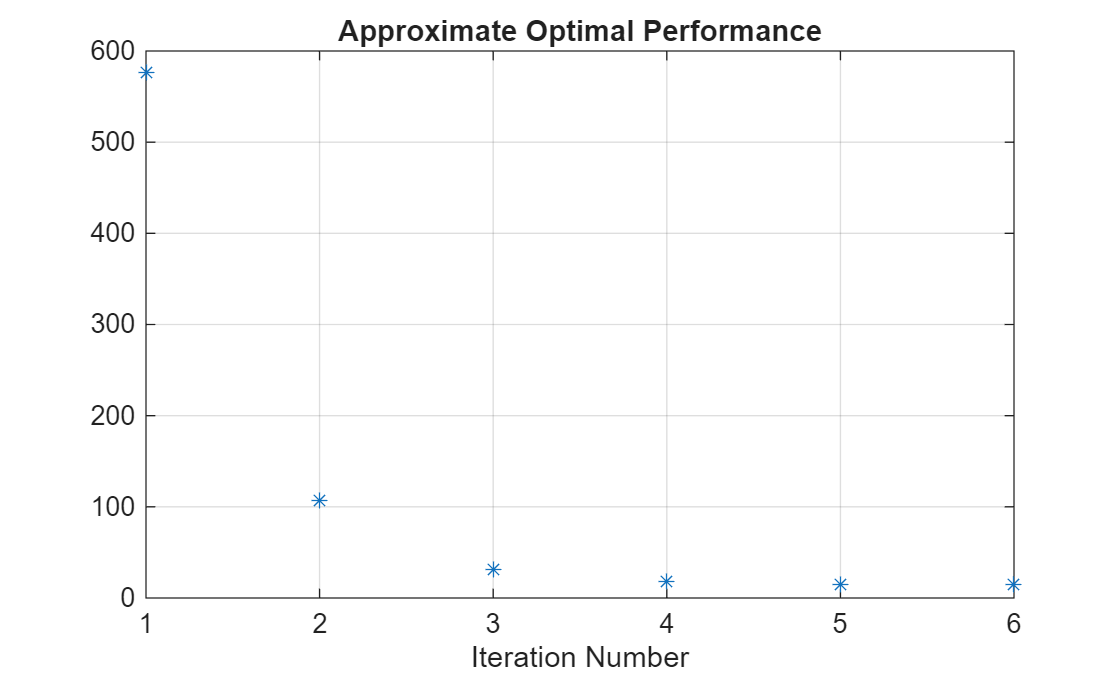

% Performance Criterion
figure (1)
plot([1:Iter],Ji,'*')
grid on
xlabel('Iteration Number')
title('Approximate Optimal Performance')

% System running time
run_time = 50

run_time = 50

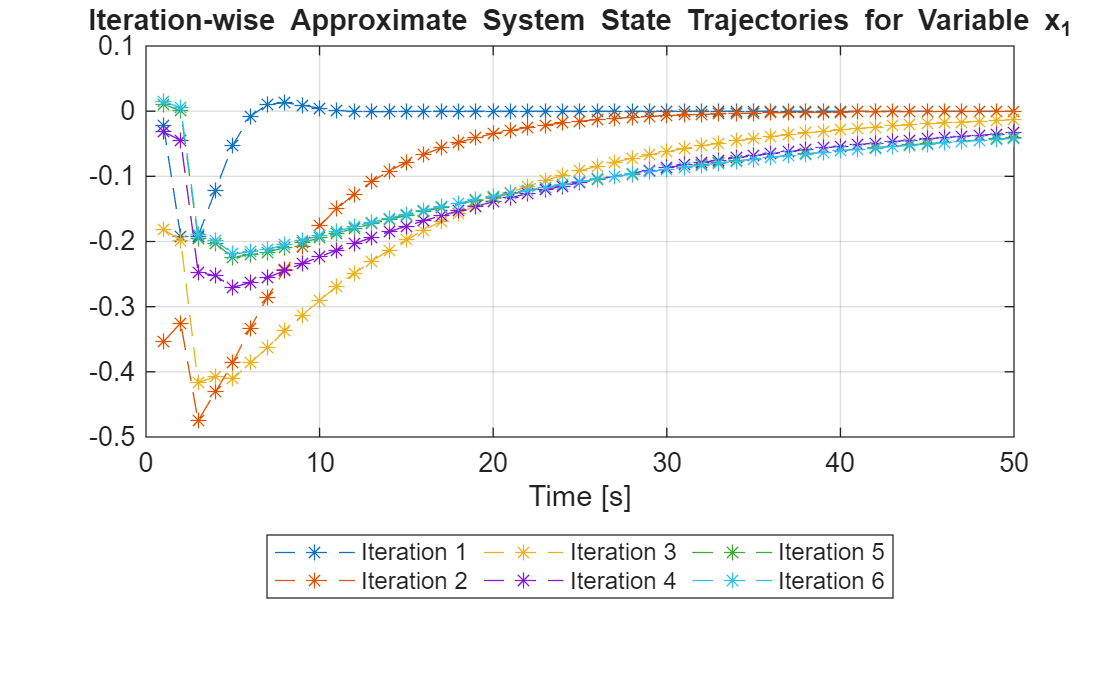

% Iteration-wise Approximate System State Trajectories Variable
figure (2)
for i=1:Iter
    Iname = sprintf('Iteration %d', i);
    k=1:1:run_time;
    for j=1:run_time
         x(:,j)=((A-B*F{i})^k(j))*x0;
    end
    plot(k,x(1,:),'*--','DisplayName',Iname)
    hold on
end
grid on
legend('NumColumns',5,'Location','southoutside'); xlabel('Time [s]'); % ylabel('State Variable x1')
title('Iteration-wise Approximate System State Trajectories for Variable x_1')

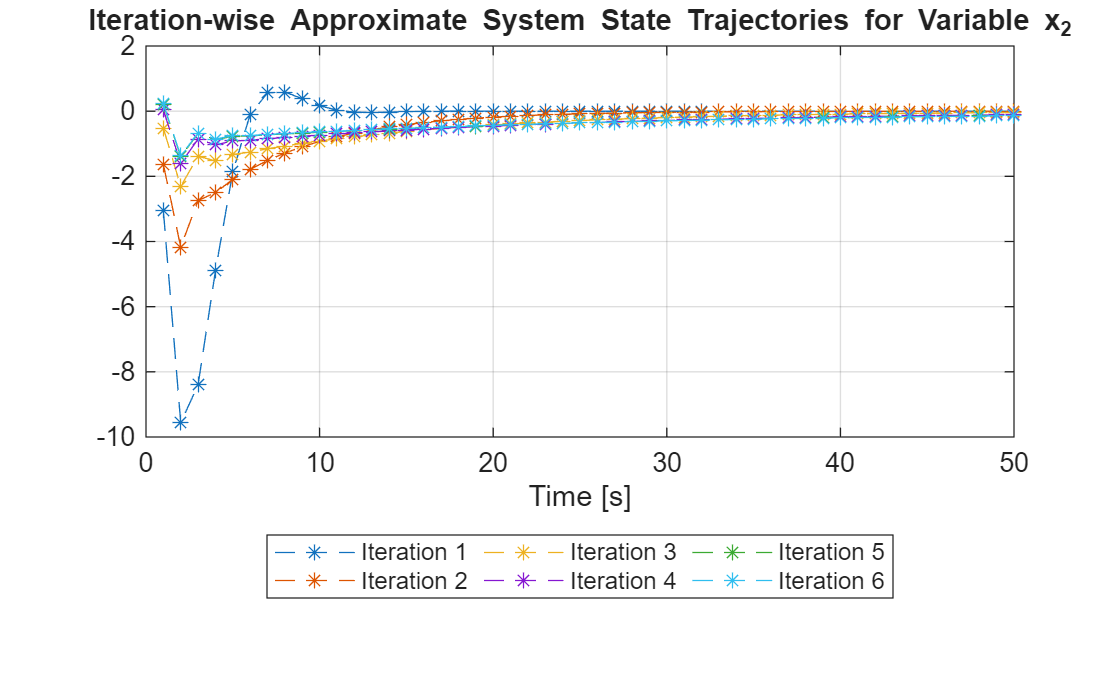


figure (3)
for i=1:Iter
    Iname = sprintf('Iteration %d', i);
    k=1:1:run_time;
    for j=1:run_time
         x(:,j)=((A-B*F{i})^k(j))*x0;
    end
    plot(k,x(2,:),'*--','DisplayName',Iname)
    hold on
end
grid on
legend('NumColumns',5,'Location','southoutside'); xlabel('Time [s]');% ylabel('State Variable x2')
title('Iteration-wise Approximate System State Trajectories for Variable x_2')

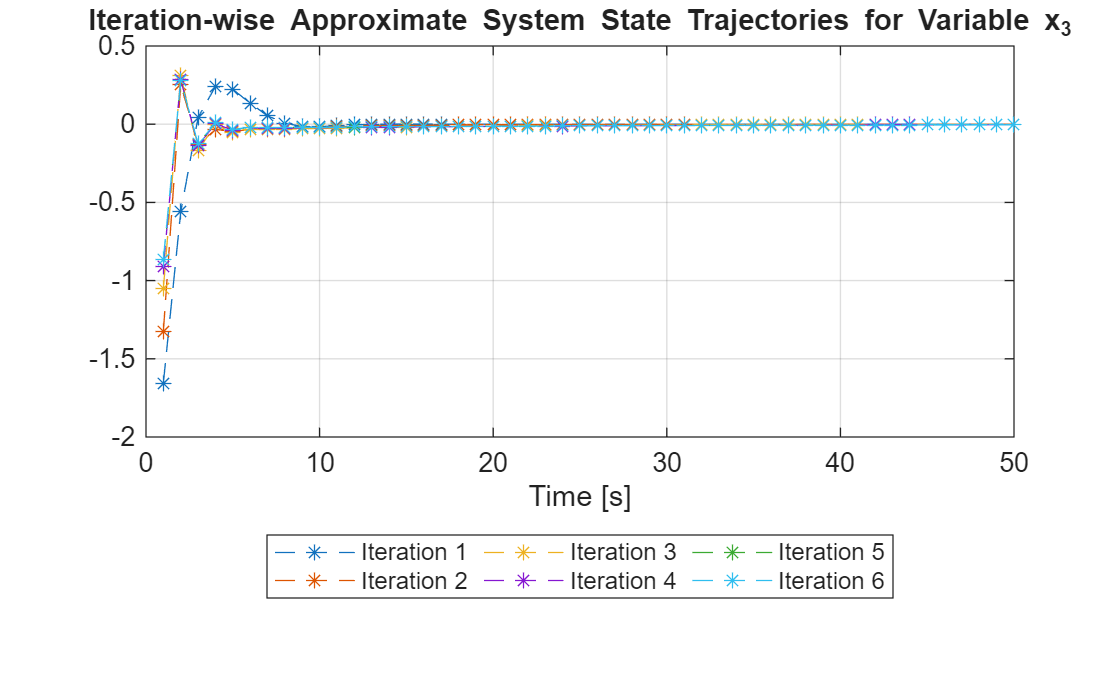


figure (4)
for i=1:Iter
    Iname = sprintf('Iteration %d', i);
    k=1:1:run_time;
    for j=1:run_time
         x(:,j)=((A-B*F{i})^k(j))*x0;
    end
    plot(k,x(3,:),'*--','DisplayName',Iname)
    hold on
end
grid on
legend('NumColumns',5,'Location','southoutside'); xlabel('Time [s]'); % ylabel('State Variable x3')
title('Iteration-wise Approximate System State Trajectories for Variable x_3')

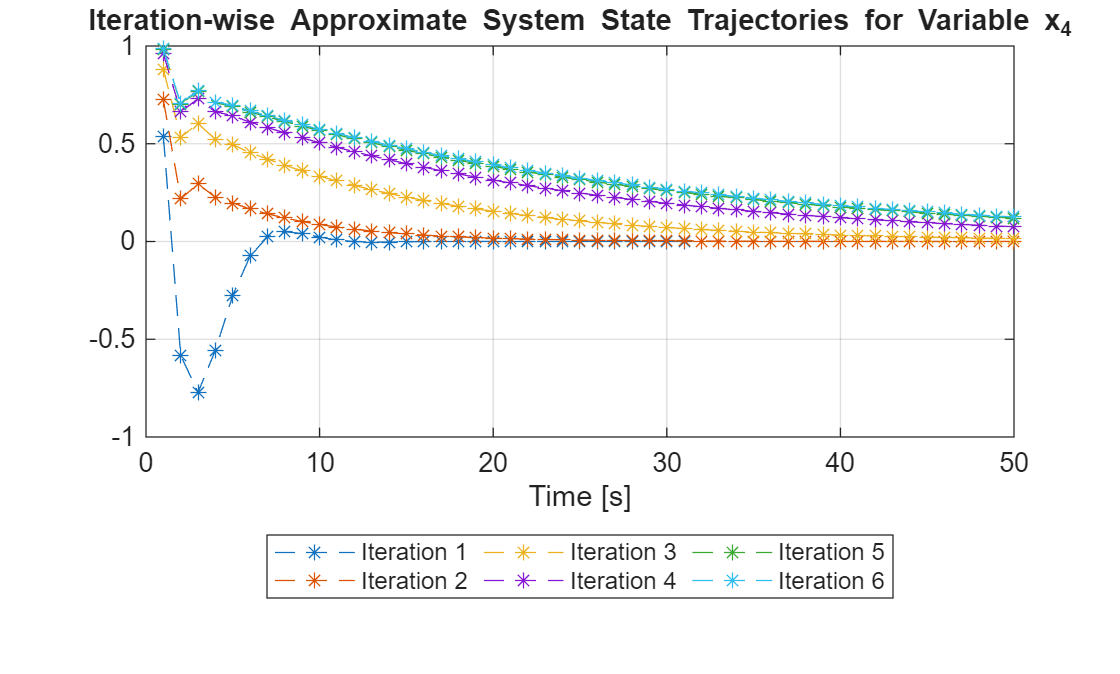


figure (5)
for i=1:Iter
    Iname = sprintf('Iteration %d', i);
    k=1:1:run_time;
    for j=1:run_time
         x(:,j)=((A-B*F{i})^k(j))*x0;
    end
    plot(k,x(4,:),'*--','DisplayName',Iname)
    hold on
end
grid on
legend('NumColumns',5,'Location','southoutside'); xlabel('Time [s]'); % ylabel('State Variable x4')
title('Iteration-wise Approximate System State Trajectories for Variable x_4')

***Further Study with RL toolbox:***

Environment set-up:

env = myDiscreteEnv(A,B,Q,R);

'myDiscreteEnv' is used in Create and Train Custom LQR Agent.

rng(0);

LQR agent creation:

agent = LQRCustomAgent(Q,R,F0);
%getActionInfo(agent)

% Set-up future reward discount factor
agent.Gamma = 1

% Set-up the number of data point to be collected before updating the critic
agent.EstimateNum = 45

LQR agent training:

% Set-up training options
trainingOpts = rlTrainingOptions(...
    MaxEpisodes=10, ...
    MaxStepsPerEpisode=50, ...
    Verbose=false);%, ...
   % Plots="training-progress");
% Training the agent
trainingStats = train(agent,env,trainingOpts);

LQR agent perfromance evaluation:

simOptions = rlSimulationOptions(MaxSteps=Iter);
experience = sim(env,agent,simOptions);
totalReward = abs(sum(experience.Reward))

Performance comparison:

Hewer_reinforcer_error = Ji(Iter) - Jopt
LQR_agent_error = totalReward - Jopt

Plot iteration-wise difference of gains 

figure (6)
% Plot the norm of the difference between the gains between the trained LQR agent and the optimal LQR solution
% Number of gain updates
len = agent.KUpdate;

% Initialize error vector
err = zeros(len,1);

% Fill elements
for i = 1:len
    err(i) = norm(agent.KBuffer{i}-Fopt);
end

% Plot logarithm of the error vector
plot(log10(err),'b*-','DisplayName','LQR Agent')
grid on
hold on

% Plot the norm of the difference between the gains between the Hewer's reinforcer and the optimal LQR solution
err_h = zeros(Iter,1);
for i=1:Iter
    err_h(i) = norm(F{i}-Fopt);
end
plot(log10(err_h),'rx-','DisplayName','Hewer reinforcer')
hold on
legend
title("Log of gain difference")
xlabel("Number of updates/iterations")